# Comparison between EMS

## Get current folder and add all folders to the path

currentpath = pwd;
currentfolder = strsplit(currentpath,filesep);
while ((~strcmp(currentfolder{end}, 'EMS-aircraft')) && ...
    (~strcmp(currentfolder{end}, 'EMS-aircraft-main')) && ...
    isempty(currentfolder{end}))
    currentpath = fileparts(currentpath);
    currentfolder = strsplit(currentpath,filesep);
end
projectpath = currentpath;
addpath(genpath(projectpath))

## Get the data folder

folder_data = strcat(projectpath,'\Data\');

## Get local data (faster than below)

PI.out = outPI;
SMC.out = outSMC;
FUZZY.out = outFUZZY;

## Get the stored data from data file


% tic
% PI = load(strcat(folder_data,'PI_300.mat'));
% SMC = load(strcat(folder_data,'SMC_300.mat'));
% FUZZY = load(strcat(folder_data,'FUZZY_300.mat'));
% toc

% tic
% PI = load(strcat(folder_data,'B20_PI_300.mat'));
% SMC = load(strcat(folder_data,'B20_SMC_300.mat'));
% FUZZY = load(strcat(folder_data,'B20_FUZZY_300.mat'));
% toc

% tic
% PI = load(strcat(folder_data,'B80_PI_85.mat'));
% SMC = load(strcat(folder_data,'B80_SMC_85.mat'));
% FUZZY = load(strcat(folder_data,'B80_FUZZY_85.mat'));
% toc

# Curves

## Voltage

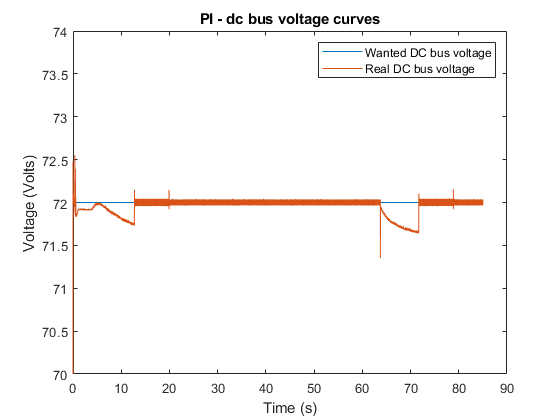

tic
bus_curve(PI,'PI');

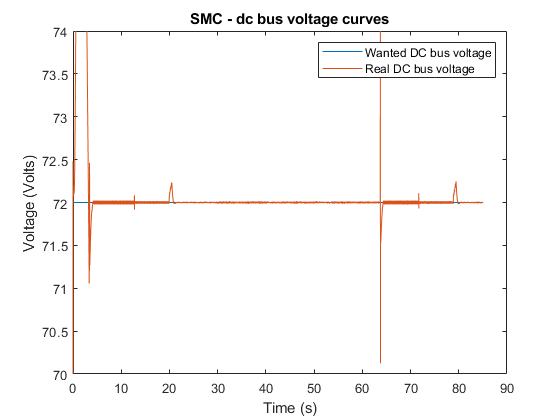

bus_curve(SMC,'SMC');

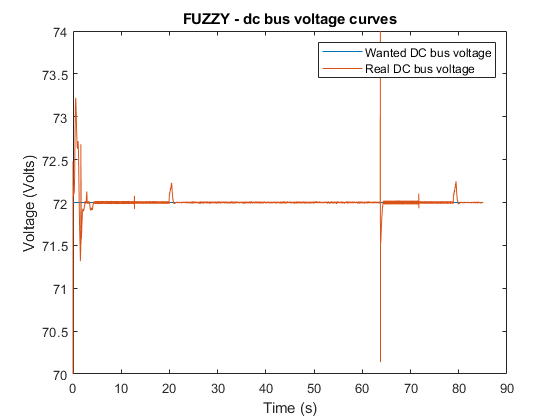

bus_curve(FUZZY,'FUZZY');

toc

Elapsed time is 6.691811 seconds.


## Power

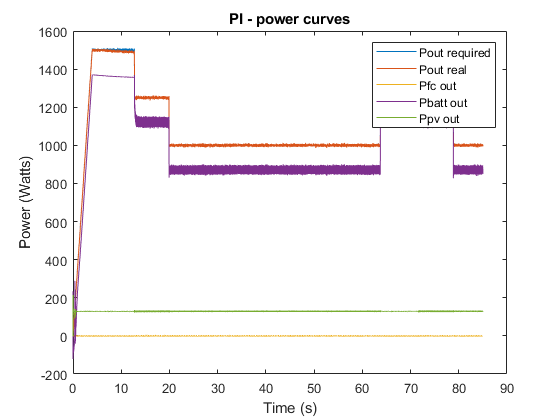

tic
power_curve(PI,'PI');

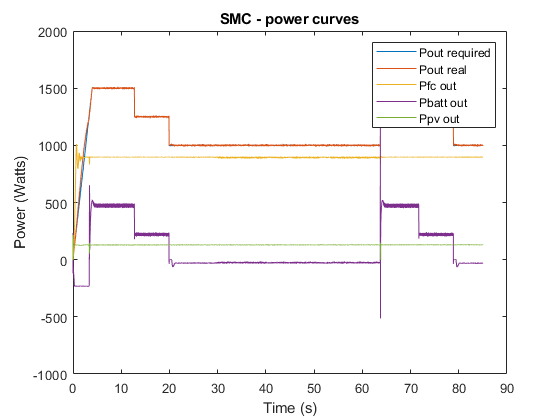

power_curve(SMC,'SMC');

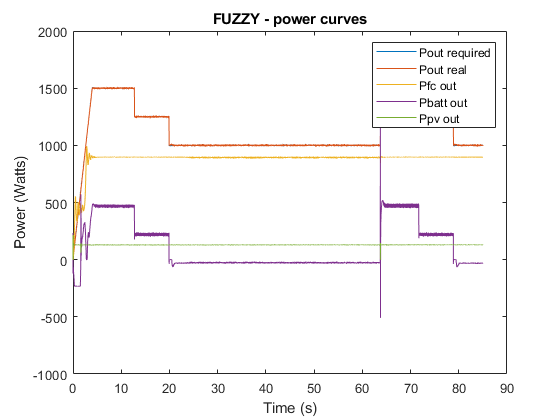

power_curve(FUZZY,'FUZZY');

toc

Elapsed time is 5.435401 seconds.


# Comparison data

## Power mean value

tic
[P_FC_in_PI, P_PV_in_PI, P_batt_in_PI, ~] = mean_power_sim(PI,'in');
[P_FC_in_SMC, P_PV_in_SMC, P_batt_in_SMC, ~] = mean_power_sim(SMC,'in');
[P_FC_in_FUZZY, P_PV_in_FUZZY, P_batt_in_FUZZY, ~] = mean_power_sim(FUZZY,'in');
[P_FC_out_PI, P_PV_out_PI, P_batt_out_PI, P_SC_PI] = mean_power_sim(PI,'out');
[P_FC_out_SMC, P_PV_out_SMC, P_batt_out_SMC, P_SC_SMC] = mean_power_sim(SMC,'out');
[P_FC_out_FUZZY, P_PV_out_FUZZY, P_batt_out_FUZZY, P_SC_FUZZY] = mean_power_sim(FUZZY,'out');


col1 = [P_FC_in_PI; P_FC_out_PI ; P_PV_in_PI; P_PV_out_PI; P_batt_in_PI; P_batt_out_PI; P_SC_PI];
col2 = [P_FC_in_SMC; P_FC_out_SMC; P_PV_in_SMC; P_PV_out_SMC; P_batt_in_SMC; P_batt_out_SMC; P_SC_SMC];
col3 = [P_FC_in_FUZZY; P_FC_out_FUZZY; P_PV_in_FUZZY; P_PV_out_FUZZY; P_batt_in_FUZZY; P_batt_out_FUZZY; P_SC_FUZZY];
row_names = {'Pfc_in','Pfc_out','Ppv_in','Ppv_out','Pbatt_in','Pbatt_out','Psc'};
column_names = {'PI','SMC','FUZZY'};
table_power = table(col1,col2,col3,'RowNames',row_names,'VariableNames',column_names)

table_power = 7×3 table
                    PI        SMC      FUZZY 
                 ________    ______    ______

    Pfc_in       0.061067    993.39    980.95
    Pfc_out      -0.98963    891.25     880.1
    Ppv_in         144.57    144.66    144.73
    Ppv_out        129.04    129.12    129.18
    Pbatt_in       1109.3    125.07    133.48
    Pbatt_out      997.94    107.91    116.44
    Psc            1.3164    2.9249     3.238


toc

Elapsed time is 2.608098 seconds.


## Error mean value

tic
[rmse_p_PI,rmse_v_PI,mep_PI, mev_PI] = error_sim(PI);
[rmse_p_SMC,rmse_v_SMC,mep_SMC, mev_SMC] = error_sim(SMC);
[rmse_p_FUZZY,rmse_v_FUZZY,mep_FUZZY, mev_FUZZY] = error_sim(FUZZY);

col11 = [rmse_p_PI;rmse_v_PI;mep_PI; mev_PI];
col22 = [rmse_p_SMC;rmse_v_SMC;mep_SMC; mev_SMC];
col33 = [rmse_p_FUZZY;rmse_v_FUZZY;mep_FUZZY; mev_FUZZY];
row_names = {'RMSE P','RMSE V','MEP (%)','MEV (%)'};
column_names = {'PI','SMC','FUZZY'};
table_error = table(col11,col22,col33,'RowNames',row_names,'VariableNames',column_names)

table_error = 4×3 table
                 PI         SMC       FUZZY  
              ________    _______    ________

    RMSE P      4.0411      14.77      1.6627
    RMSE V    0.099412    0.76371      0.0989
    MEP        0.15312    0.40592    0.061719
    MEV        0.07665    0.19739    0.030805


toc

Elapsed time is 0.533500 seconds.


## Consumption / SOC / SOH / age

tic
[chydro_PI, Batt_SOC_PI, Batt_SOH_PI,age_PI] = consumption_sim(PI);
[chydro_SMC, Batt_SOC_SMC, Batt_SOH_SMC,age_SMC] = consumption_sim(SMC);
[chydro_FUZZY, Batt_SOC_FUZZY, Batt_SOH_FUZZY,age_FUZZY] = consumption_sim(FUZZY);

col111 = [chydro_PI; Batt_SOC_PI; Batt_SOH_PI;age_PI];
col222 = [chydro_SMC; Batt_SOC_SMC; Batt_SOH_SMC; age_SMC];
col333 = [chydro_FUZZY; Batt_SOC_FUZZY; Batt_SOH_FUZZY; age_FUZZY];

row_names = {'H2 cons','SOC','SOH','age'};
column_names = {'PI','SMC','FUZZY'};
table_consu = table(col111,col222,col333,'RowNames',row_names,'VariableNames',column_names)

table_consu = 4×3 table
                   PI          SMC       FUZZY 
               __________    _______    _______

    H2 cons    8.0729e-05     1.3656     1.3457
    SOC            76.548     79.617     79.592
    SOH           0.96548    0.99617    0.99592
    age                 1    0.99906    0.99907


toc

Elapsed time is 0.325597 seconds.
